## (ai)

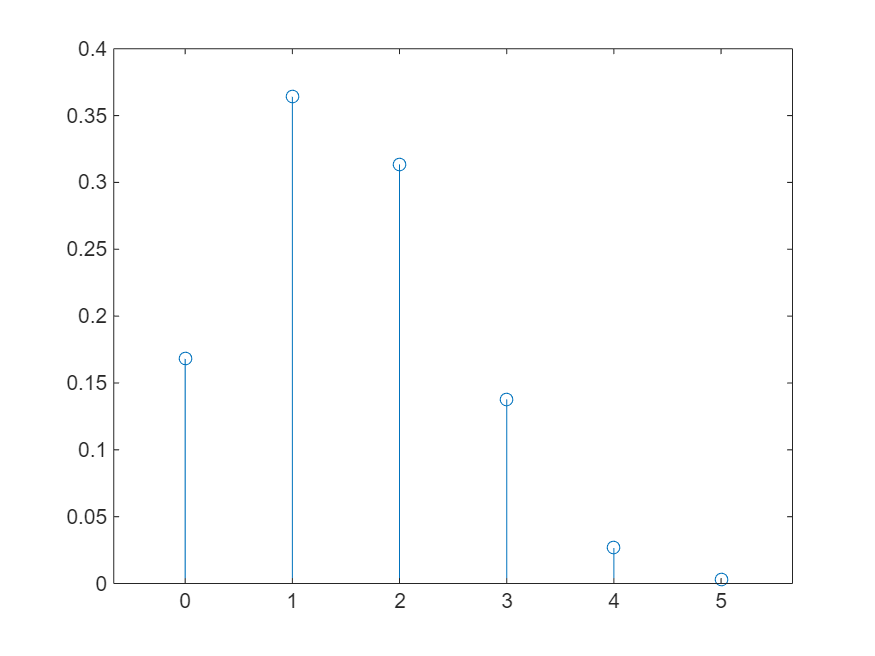

N = 10000;
p = 0.3;
n = 5;
s = 0:5;
pX = zeros(1, 6);

for i = 1:6
    k = i-1;
    count = 0;
    for j = 1:N
        am = rand(1, n) < p;
        def = sum(am);
        if def == k
            count = count+1;
        end
    end
    pX(i) = count / N;
end

stem(s, pX);

## (aii)

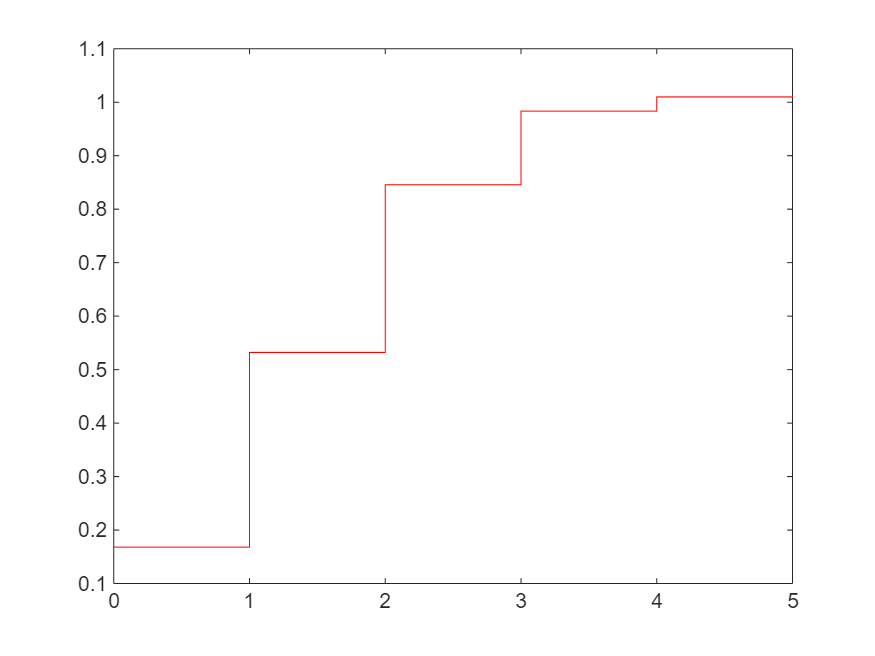

x = 0:5;
fd = cumsum(pX);

stairs([0 1 2 3 4 5],fd,'r')

## (aiii)

pX(1) + pX(2) + pX(3)

ans = 0.8456

## (bi)

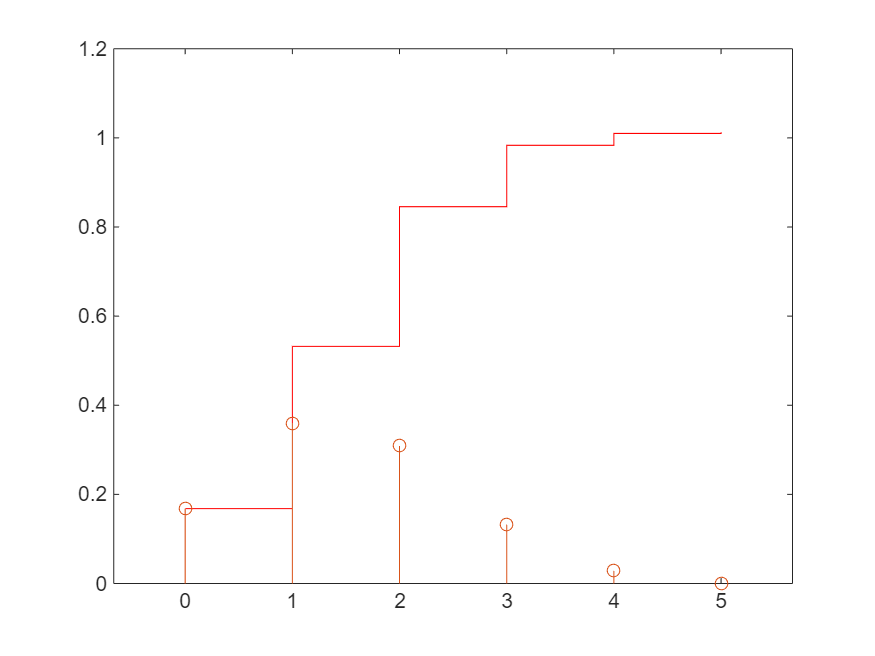

n = 5;
p = 0.3;
pX = zeros(1,6);

for i = 1:5
    k = i - 1;
    pX(i) = factorial(n) / (factorial(k) * factorial(n-k)) * p^k * (1-p)^(n-k);
end

figure(1);
hold on;

x = 0:5;
stem(x,pX);

## (bii)

p = pX(1) + pX(2) + pX(3)